[file,path] = uigetfile('*.csv');
file_name = fullfile(path, file);
file_contents = fileread(file_name);
csv_signature = "BEGIN CSV";
content_begin = regexp(file_contents, csv_signature);
content_end = regexp(file_contents, '\n.*$', 'end');

if isempty(content_begin)
    error("Did not find CSV signature in file")
end

data = file_contents(content_begin+10:content_end);

FID = fopen('temp.csv', 'w');
fprintf(FID, data);
fclose(FID);

data = readtable('temp.csv', 'Delimiter', ',');
data = data(1:end-1, :);

if any("X_Mallet_cm_" == string(data.Properties.VariableNames))
    data.X_Puck_cm_ = data.X_Mallet_cm_;
    data.Y_Puck_cm_ = data.Y_Mallet_cm_;
end

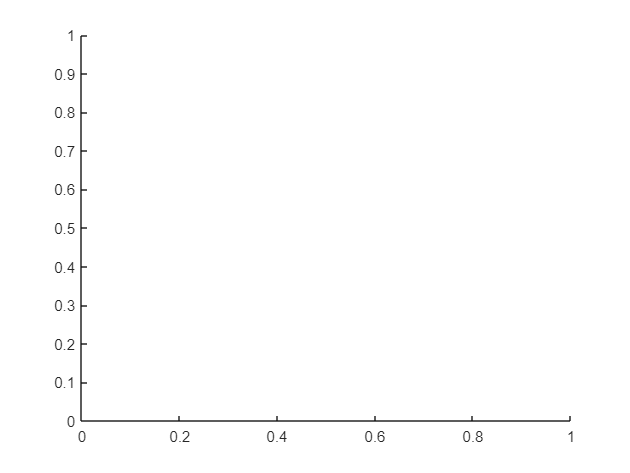

% load('slowcloverpid.mat')
figure
hold on

plot(data.Time_ms_, data.Left_PWM)

Error using  . 
Unrecognized table variable name 'Time_ms_'.

plot(data.Time_ms_, data.Right_PWM)

mean(abs(data.Left_PWM))
mean(abs(data.Right_PWM))

median(abs(data.Left_PWM))
median(abs(data.Right_PWM))

std(abs(data.Left_PWM))
std(abs(data.Right_PWM))

figure
hold on
plot(data.Time_ms_, data.Left_PID)
plot(data.Time_ms_, data.Left_Feed_Forward)
legend('PID', 'FeedForward')

figure
hold on
plot(data.Time_ms_, data.Right_PID)
plot(data.Time_ms_, data.Right_Feed_Forward)
legend('PID', 'FeedForward')

figure
hold on
grid on
plot(data.Time_ms_, data.X_Target_cm_)
plot(data.Time_ms_, data.X_Puck_cm_)
plot(data.Time_ms_, data.X_Puck)
legend('Target', 'Actual', 'Puck')

figure
hold on
grid on
plot(data.Time_ms_, data.Y_Target_cm_)
plot(data.Time_ms_, data.Y_Puck_cm_)
plot(data.Time_ms_, data.Y_Puck)
legend('Target', 'Actual','Puck')

figure
hold on
plot(data.Time_ms_, data.X_Target_cm_ - data.X_Puck_cm_)
plot(data.Time_ms_, data.Y_Target_cm_ - data.Y_Puck_cm_)
legend('X Error', 'Y Error', 'Norm Error')

figure
hold on
plot(data.X_Target_cm_, data.Y_Target_cm_)
plot(data.X_Puck_cm_, data.Y_Puck_cm_)
xlabel('x(cm)')
ylabel('y(cm)')
% xlim([0, 100])
% ylim([0, 100])
title('Clover')
legend('Target', 'Actual')
legend('Target', 'Actual', location='best')

% Y_Puckcm = -(data.Left_Angledeg - data.Right_Angledeg) * 3.5 * pi / 360;
% X_Puckcm = (data.Left_Angledeg + data.Right_Angledeg) * 3.5 * pi / 360;
% figure
% plot(X_Puckcm, Y_Puckcm)

% figure
% hold on
% plot(data.Time_ms_, data.X_Puck_cm_);   
% plot(data.Time_ms_, data.X_Target_cm_);

X_error = data.X_Target_cm_ - data.X_Puck_cm_;
Y_error = data.Y_Target_cm_ - data.Y_Puck_cm_;
mean_abs_x_error = mean(abs(X_error))*10
mean_abs_y_error = mean(abs(Y_error))*10
mean_abs_error = mean(sqrt(X_error.^2 + Y_error.^2)) * 10

figure
hold on
plot(data.X_Puck, data.Y_Puck)
axis equal
xlim([0, 100])
ylim([0, 200])
xlabel('x(cm)')
ylabel('y(cm)')
title('Puck')

% figure
% hold on
% plot(data.X_Target_cm_, data.Y_Target_cm_)
% plot(data.X_Puck_cm_, data.Y_Puck_cm_)
% xlabel('x(cm)')
% ylabel('y(cm)')
% xlim([0, 100])
% ylim([0, 100])
% 
% n = length(data.Time_ms_) ;
% for i = 1:50:n
%     plot(data.X_Puck_cm_(i),data.Y_Puck_cm_(i), 'or')
%     plot(data.X_Target_cm_(i),data.Y_Target_cm_(i), 'ob')
%     drawnow
% end

% figure
% hold on
% plot(data.Time_ms_, gradient(data.Y_Puck))

figure
hold on
plot(data.X_Target_cm_, data.Y_Target_cm_)
plot(data.X_Puck_cm_, data.Y_Puck_cm_)
plot(data.X_Puck, data.Y_Puck)
xlabel('x(cm)')
ylabel('y(cm)')
xlim([0, 100])
ylim([0, 100])
legend('Target', 'Actual')
legend('Target', 'Actual', 'Puck', location='best')

for i=0:0.1:0.9
    startIdx = round(1 + i*length(data.Time_ms_));
    endIdx = round((i+0.1)*length(data.Time_ms_));
    figure
    hold on
    plot(data.X_Target_cm_(startIdx:endIdx), data.Y_Target_cm_(startIdx:endIdx))
    plot(data.X_Puck_cm_(startIdx:endIdx), data.Y_Puck_cm_(startIdx:endIdx))
    plot(data.X_Puck(startIdx:endIdx), data.Y_Puck(startIdx:endIdx))
    plot(data.X_Puck(startIdx), data.Y_Puck(startIdx), 'or')
    xlabel('x(cm)')
    ylabel('y(cm)')
    xlim([0, 100])
    ylim([0, 200])
    legend('Target', 'Actual')
    legend('Target', 'Actual', 'Puck', location='best')
    % pause();
end
